obj =   DataLoader with properties:

              type: 'car'
             scene: '005'
        gt_regions: {}
             image: {[1024×1024 uint8]  [1024×1024 uint8]  [1024×1024 uint8]  [1024×1024 uint8]  [1024×1024 uint8]  [1024×1024 uint8]  [1024×1024 uint8]  [1024×1024 uint8]  [1024×1024 uint8]  [1024×1024 uint8]  [1024×1024 uint8]}
       frame_range: [1 11]
          interval: 11
              diff: []
         mean_diff: []
                th: []
           outlier: []
        and_output: []
    before_growing: []
        hblob_area: []
    hblob_centroid: []
        hblob_bbox: []
    output_regions: []


obj =   DataLoader with properties:

              type: 'car'
             scene: '005'
        gt_regions: {1×326 cell}
             image: {[1024×1024 uint8]  [1024×1024 uint8]  [1024×1024 uint8]  [1024×1024 uint8]  [1024×1024 uint8]  [1024×1024 uint8]  [1024×1024 uint8]  [1024×1024 uint8]  [1024×1024 uint8]  [1024×1024 uint8]  [1024×1024 uint8]}
       frame_range: [1 11]
          interval: 11
              diff: {[1024×1024 uint8]  [1024×1024 uint8]  [1024×1024 uint8]  [1024×1024 uint8]  [1024×1024 uint8]  [1024×1024 uint8]  [1024×1024 uint8]  [1024×1024 uint8]  [1024×1024 uint8]  [1024×1024 uint8]}
         mean_diff: [2.8804 2.9464 3.0145 2.9322 2.9363 2.3456 3.7033 2.3114 3.7060 2.3699]
                th: [8.6289 8.8267 9.0307 8.7842 8.7963 7.0269 11.0941 6.9243 11.1021 7.0996]
           outlier: {[1024×1024 logical]  [1024×1024 logical]  [1024×1024 logical]  [1024×1024 logical]  [1024×1024 logical]  [1024×10

extent_th =          0    0.7000


area_th =     10    70


ex_hist =   Histogram with properties:

             Data: [180×1 double]
           Values: [1 8 17 35 42 46 11 7 13]
          NumBins: 9
         BinEdges: [0.1000 0.2000 0.3000 0.4000 0.5000 0.6000 0.7000 0.8000 0.9000 1]
         BinWidth: 0.1000
        BinLimits: [0.1000 1]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


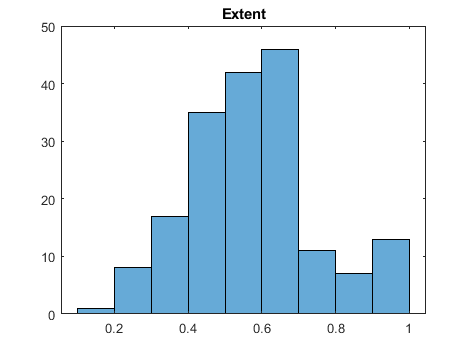

ec_hist =   Histogram with properties:

             Data: [180×1 double]
           Values: [3 1 1 3 4 12 24 43 46 43]
          NumBins: 10
         BinEdges: [0 0.1000 0.2000 0.3000 0.4000 0.5000 0.6000 0.7000 0.8000 0.9000 1]
         BinWidth: 0.1000
        BinLimits: [0 1]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


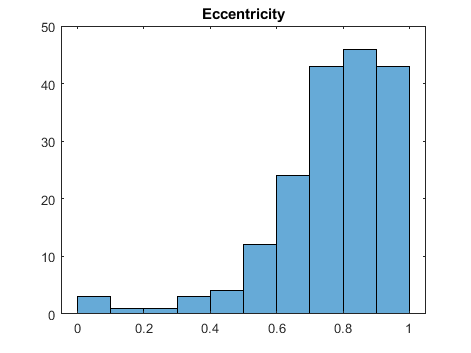

maj_hist =   Histogram with properties:

             Data: [180×1 double]
           Values: [3 60 59 28 25 2 0 1 1 0 1]
          NumBins: 11
         BinEdges: [0 3 6 9 12 15 18 21 24 27 30 33]
         BinWidth: 3
        BinLimits: [0 33]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


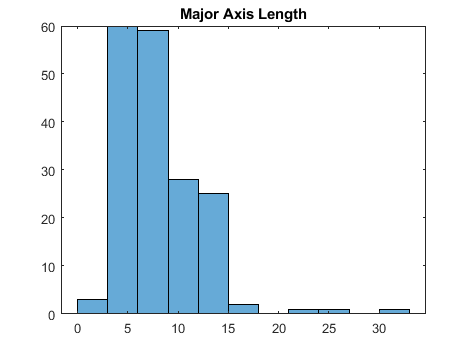

area_hist =   Histogram with properties:

             Data: [180×1 int32]
           Values: [60 49 28 12 11 5 4 3 4 1 3]
          NumBins: 11
         BinEdges: [0 10 20 30 40 50 60 70 80 90 100 110]
         BinWidth: 10
        BinLimits: [0 110]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


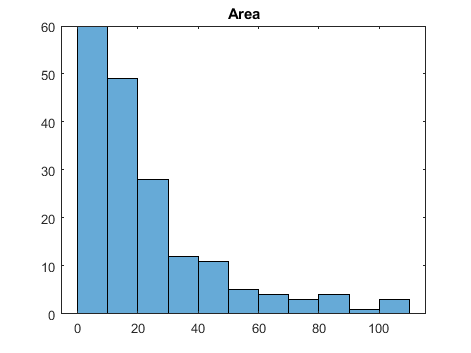

car = DataLoader('car', 5, [1, 11]);

montage(car.image, BackgroundColor=[0.5 0.5 0.5], BorderSize=[5 5])

imgOverlays = {};
imgOverlays_beforeGrowing = {}


imgOverlays_beforeGrowing =

  0×0 empty cell array



imgOverlays_both = {}


imgOverlays_both =

  0×0 empty cell array



for i=1:(car.interval-2)
    imgOverlays{i}=imoverlay(car.image{i+2}, car.and_output{i}, 'yellow');
    imgOverlays_beforeGrowing{i}=imoverlay(car.image{i+2}, car.before_growing{i}, 'cyan');
    imgOverlays_both{i}=imoverlay(imgOverlays{i}, car.before_growing{i}, 'cyan');
end

%montage([car.diff car.outlier car.and_output, imgOverlays], ...
%    BackgroundColor=[0.5 0.5 0.5], BorderSize=[5 5])

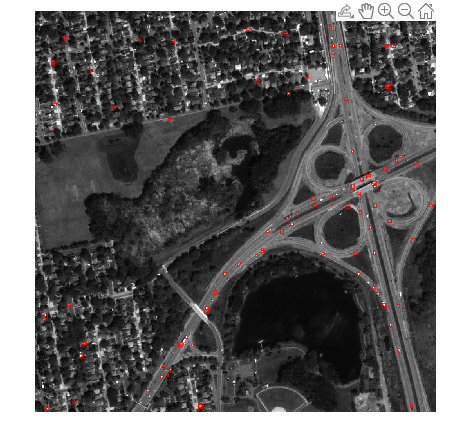

%shape=insertShape(car.image{7},'rectangle',car.hblob_bbox{5}, 'Linewidth',1);

%imshow(imgOverlays_beforeGrowing{5})
%imshow(imgOverlays{5})
%imshow(imgOverlays_both{5})
imshow(car.image{7});
for i=1:(size(car.output_regions{5}, 1))
    hold on
    %car.output_regions{5}
    rectangle('Position', car.output_regions{5}(i, :), 'EdgeColor','r')
    %rectangle('Position', car.gt_regions{7}(i, :), 'EdgeColor','r')
end

% car.image{5}

